clear;
close all;
warning('off', 'all');
raw_data = readtable('./output/WAR_SIMULATION_04_02_56_18_04_2025.txt');
p = (size(raw_data, 2) - 1)/4;
actions = cell(1, p);
action_intervals = cell(1, p);
leg = cell(1, p);
max_intervals = 0;
action_types = {'Null'};
for i = 1:p
    leg{i} = ['Nation ', num2str(i - 1)];
    action_intervals{i} = 1;
    n_intervals = 1;
    actions{i} = {raw_data{1, ['NATION', num2str(i - 1), 'ACTION']}{:}};
    for t = 2:size(raw_data, 1)
        if table2array(raw_data(t, ['NATION', num2str(i - 1), 'S'])) > 0
            action = raw_data{t, ['NATION', num2str(i - 1), 'ACTION']}{:};
            if sum(strcmp(action_types, action)) == 0
                action_types{length(action_types) + 1} = action;
            end
            if strcmp(action, actions{i}{n_intervals})
                action_intervals{i}(n_intervals) = action_intervals{i}(n_intervals) + 1;
            else
                action_intervals{i} = [action_intervals{i}; 1];
                n_intervals = n_intervals + 1;
                actions{i}{n_intervals} = action;
            end
        end
    end
    if length(action_intervals{i}) > max_intervals
        max_intervals = length(action_intervals{i});
    end
end

action_colors = zeros(size(action_types, 2), 3);
rng(10);
for i = 1:length(action_types)
    c = rand([1, 3]);
    action_colors(i, :) = c/norm(c, 2);
end

action_bars = zeros(p, max_intervals);

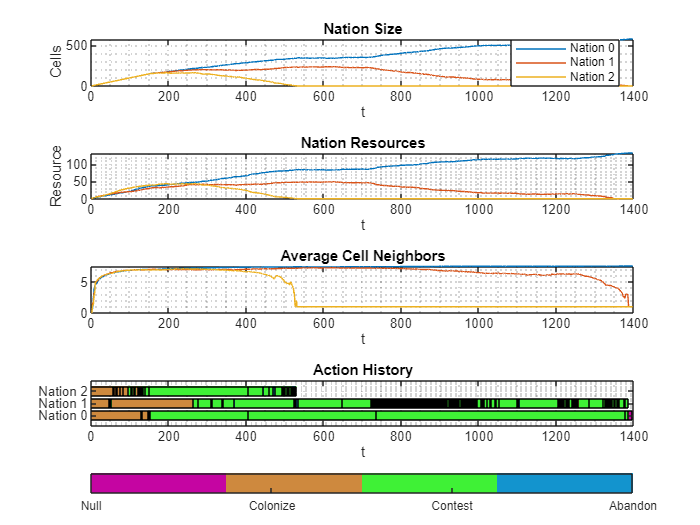

f = figure;
tiledlayout(4, 1, "TileSpacing","loose", 'Padding','loose');
colormap(action_colors);
for i = 1:p
    nexttile(1);
    plot(raw_data, "t", ['NATION', num2str(i - 1), 'S']);
    grid minor;
    title("Nation Size");
    ylabel("Cells");
    hold on;

    nexttile(2);
    plot(raw_data, "t", ['NATION', num2str(i - 1), 'R']);
    grid minor;
    title("Nation Resources");
    ylabel("Resource");
    hold on;

    nexttile(3);
    plot(raw_data, "t", ['NATION', num2str(i - 1), 'A_BAR']);
    grid minor;
    title("Average Cell Neighbors");
    hold on;

    nexttile(4);
    b = barh(leg(i), action_intervals{i}', 'stacked');
    grid minor;
    for j = 1:length(b)
        b(j).FaceColor = action_colors(strcmp(action_types, actions{i}{j}), :);
    end
    title("Action History");
    xlabel("t");
    hold on;
end
nexttile(1);
legend(leg, 'location', 'best');
cb = colorbar('Ticks', linspace(0, 1, length(action_types)), 'TickLabels', action_types);
cb.Layout.Tile = 'south';